clear
clc
ulogOBJ = ulogreader("log_3_2021-6-30-08-16-14.ulg");
msg = readTopicMsgs(ulogOBJ);

## 获取数据

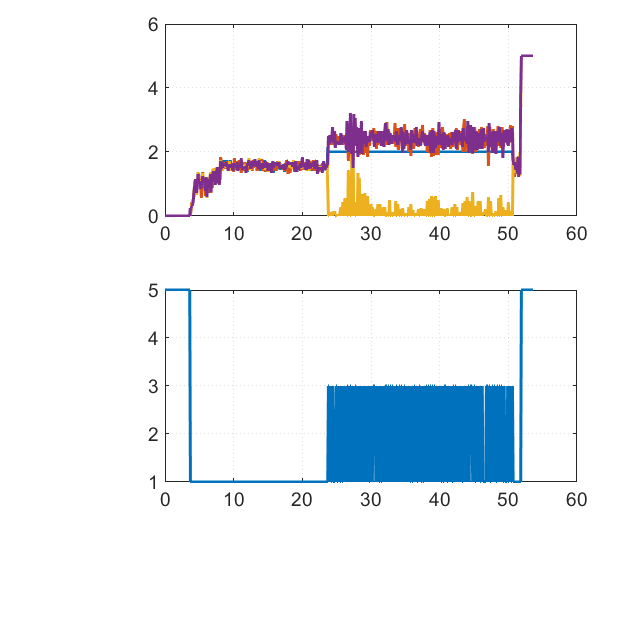

% 获取known_logger数据
logSampleRate = 10;
known_logger = msg.TopicMessages{16};
% 生成相对时间
log_time = known_logger.timestamp;
[sample_count,~] = size(log_time);
relativeTime = 0:1/logSampleRate:((sample_count-1)*(1/logSampleRate));

iter = known_logger.iter;
tDes = known_logger.tdes;

figure(1)
clf
subplot(2,1,1)
plot(relativeTime,tDes)
subplot(2,1,2)
plot(relativeTime,iter)